## Signal Generation

fs = 1000;
dt = 0.07;
aquisition_time = 10*dt; % guess
nr_samples = round(fs*aquisition_time);
aquisition_time = nr_samples./fs; % actual
t = linspace(0,aquisition_time,nr_samples);


wave_type = "Square";
wave_f = 8;
wave_vpp = 5;
wave_vpp2 = 4;
nr_synthesis = 25;
wave_amp = wave_vpp/2;
wave_amp2 = wave_vpp2/2;

if wave_type == "Sinusoidal"
    y_orig = sin(wave_f.*2.*pi.*t);
elseif wave_type == "Square"
    y_orig = wavesquare(wave_f,t);
elseif wave_type == "Triangle"
    y_orig = wavetriangle(wave_f,t);
elseif wave_type == "Synthesized Triangle"
    y_orig = FStrianglewave(wave_f,t,nr_synthesis);
elseif wave_type == "Synthesized Square"
    y_orig = FSsquarewave(wave_f,t,nr_synthesis);
elseif wave_type == "Triangle Mix Square"
   y_orig = min(wave_amp*abs(FStrianglewave(wave_f,t,nr_synthesis)), ...
       wave_amp2*abs(FSsquarewave(wave_f,t,nr_synthesis)));
   y_orig = y_orig./max(y_orig);
   y_orig = sign(FSsquarewave(wave_f,t,nr_synthesis)).*y_orig;
end

wave_noise_max_amp = 0.5;
has_noise = false;
if ~has_noise && 1==1
    wave_noise_max_amp = 0;
end

y_source = wave_amp.*y_orig;

## Signal Modification

% Determine aquisition mode
aquisition_type = "Average";
if aquisition_type == "Average"
    repeats = 20;
else
    repeats = 1;
end

y_samples = zeros(nr_samples,repeats);
for i = 1:repeats
    % Noise
    y = y_source';
    if has_noise && 1 == 1 % removes unreach warning
        y = y + (wave_noise_max_amp*rand(nr_samples,1) - ...
        wave_noise_max_amp/2);  
    end
    y_primary = y';
    
    % Filtering
    filter_type = "None";
    lower_bound = 8; upper_bound = 300;
    assert(lower_bound < upper_bound);
    
    if filter_type == "Band-Pass"
         y = o1filter(y',fs,lower_bound,"high-pass")';
         y = o1filter(y',fs,upper_bound,"low-pass")';
    elseif filter_type == "Low-Pass"
        y = o1filter(y',fs,upper_bound,"low-pass")';
    elseif filter_type == "High-Pass"
        y = o1filter(y',fs,lower_bound,"high-pass")';
    end
    
    y_filter = y';
    
    % Windowing
    window_type = "Hanning";
    win_ref = wave_amp.*ones(1,nr_samples);
    if window_type == "Hanning"
        y = hann(nr_samples).*y; 
        win_ref = hann(nr_samples).*wave_amp;
    elseif window_type == "Gaussian"
        y = gausswin(nr_samples).*y;
        win_ref = gausswin(nr_samples).*wave_amp;
    end
    
    y_window = y'; % to plot later
    y_samples(:,i) = y;
end
y_aquisition = sum(y_samples,2)'./repeats;

% Fourier Transform
[Y,f] = fft2NdB(y_aquisition,fs);
if true&& 1 == 1
    flower = 0; fupper = 100;
else
    flower = f(1); fupper = f(end);
end

if fupper >= 1000000
    fplot_divisor = 1000000;
    funit = "M";
elseif fupper >= 1000
    fplot_divisor = 1000;
    funit = "k";
else
    fplot_divisor = 1;
    funit = "";
end

t_orig = t;
if t <= 1e-6
    t = t/1e-9;
    t_unit = "n";
elseif t <= 1e-3
    t = t/1e-6;
    t_unit = "\mu";
elseif t <= 1
    t = t/1e-3;
    t_unit = "m";
else
    t_unit = "";
end

% Plotting

clf

fprintf("Record Length: %u\n" + ...
    "Aquisition Time: %1.3e seconds\n",...
    nr_samples,aquisition_time);

Record Length: 700
Aquisition Time: 7.000e-01 seconds


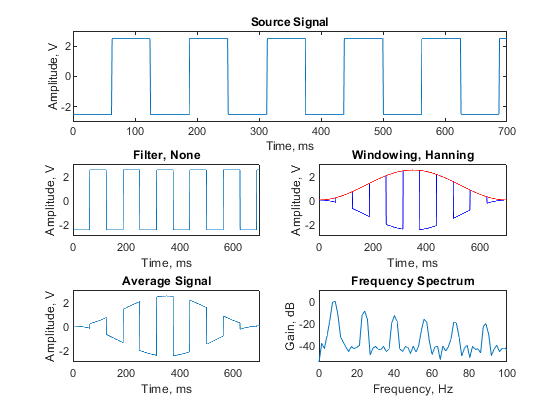


subplot(3,2,[1 2])
plot(t,y_primary)
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
title("Source Signal")
xlabel(sprintf("Time, %s%s",t_unit,"s"));
ylabel("Amplitude, V")

subplot(3,2,3)
plot(t,y_filter);
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
title("Filter, " + filter_type)
xlabel(sprintf("Time, %s%s",t_unit,"s"));
ylabel("Amplitude, V")

subplot(3,2,4)
plot(t,y_window,'b',t,win_ref,'r');
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
title("Windowing, " + window_type)
xlabel(sprintf("Time, %s%s",t_unit,"s"));
ylabel("Amplitude, V")
% legend({'Signal','Windowing function'})

if aquisition_type == "Average"
    subplot(3,2,5)
    plot(t,y_aquisition)
    axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
    title("Average Signal")
    xlabel(sprintf("Time, %s%s",t_unit,"s"));
    ylabel("Amplitude, V")
    subplot(3,2,6)
else
    subplot(3,2,[5,6])
end
plot(f/fplot_divisor,Y);
axis([flower/fplot_divisor fupper/fplot_divisor min(Y) 10])
title("Frequency Spectrum")
xlabel(sprintf("Frequency, %sHz",funit));
ylabel("Gain, dB")

if false&& wave_type ~= "Sinusiodal"
    if wave_type == "Synthesized Square" || wave_type == "Square"
        c_peak = wave_amp.*4./pi./(1:2:nr_synthesis*2);
        f_peak = wave_f.*(1:2:nr_synthesis*2);
    elseif wave_type == "Synthesized Triangle" || wave_type == "Triangle"
        c_peak = wave_amp.*8./pi^2./(1:2:nr_synthesis*2).^2;
        f_peak = wave_f.*(1:2:nr_synthesis*2);
    end
    hold on
    plot(f_peak,20*log10(c_peak/max(c_peak)),'o')
    hold off
end

% Highlight peaks
if false&& 1 == 1
    [pks, fpks] = findpeaks(Y,f);
    hold on
    plot(fpks,pks,'ro')
    hold off
else
    pks = 0;
    fpks = 0;
end

## Save Data

fName = "VisaSanti.mat"; 
if fName ~= ""
    r = struct;
    r.SampleRate = fs;
    r.RecordLength = nr_samples;
    r.SignalType = wave_type;
    r.SignalFrequency = wave_f;
    r.SignalAmplitudePP = wave_vpp;
    r.NrAquisitions = repeats;
    r.NoiseAmplitude = wave_noise_max_amp;
    r.FilterType = filter_type;
    r.FilterUpperBound = upper_bound;
    r.FilterLowerBound = lower_bound;
    r.WindowType = window_type;
    r.SourceSignal = y_primary;
    r.FilterSignal = y_filter;
    r.WindowSignal = y_window;
    r.AvarageSignal = y_aquisition;
    r.FrequencyDomain = Y;
    r.Time = t_orig;
    r.Frequency = f;
    r.Peaks = pks;
    r.PeakFreq = fpks;
    save(fName,"r");
else
    fprintf("No filename supplied")
end